load parkingTrainGTunfinished2.mat gTruth
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [500×3 table]


[imds, blds] = objectDetectorTrainingData(gTruth);

countEachLabel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     215        181    
    Charger        135        135    
    EV             281        255    


bboxes = createBoundingBoxTable(blds)

bboxes = 631×3 table
    ImgIdx              BBox                Label   
    ______    ________________________    __________

       1      197    106     81    109    EV        
       2      127     26    230    257    EV        
       3      202     80     81    159    Charger   
       4      183     90    118    137    EV        
       5      127     31    221    260    EV        
       6      246    141     10     11    Accessible
       6      129    143      7      7    Accessible
       6       59    144      7      7    Accessible
       6      331     54     93    112    EV        
       7      227    119     77     77    Accessible
       8      133    261     83     59    Charger   
       8      188     90    105    144    EV        
       9       87     97    317    126    Accessible
      10      221    142     29     38    Accessible
      11      205    116    

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 631×5 table
    ImgIdx              BBox                Label       Area     AspectRatio
    ______    ________________________    __________    _____    ___________

       1      197    106     81    109    EV             8829      0.74312  
       2      127     26    230    257    EV            59110      0.89494  
       3      202     80     81    159    Charger       12879      0.50943  
       4      183     90    118    137    EV            16166      0.86131  
       5      127     31    221    260    EV            57460         0.85  
       6      246    141     10     11    Accessible      110      0.90909  
       6      129    143      7      7    Accessible       49            1  
       6       59    144      7      7    Accessible       49            1  
       6      331     54     93    112

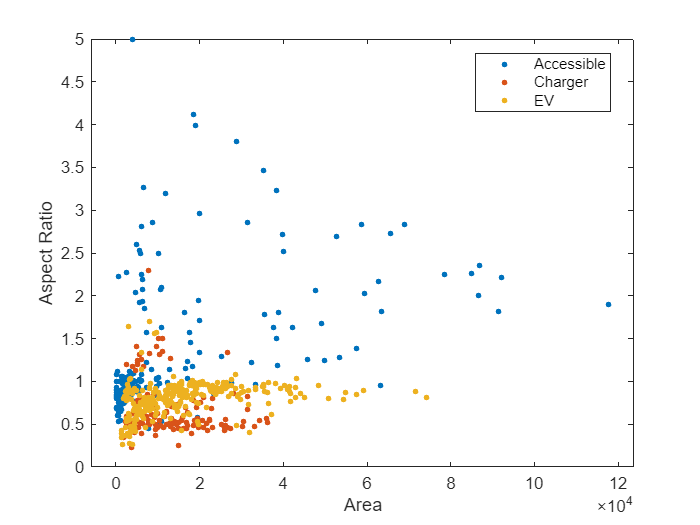

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

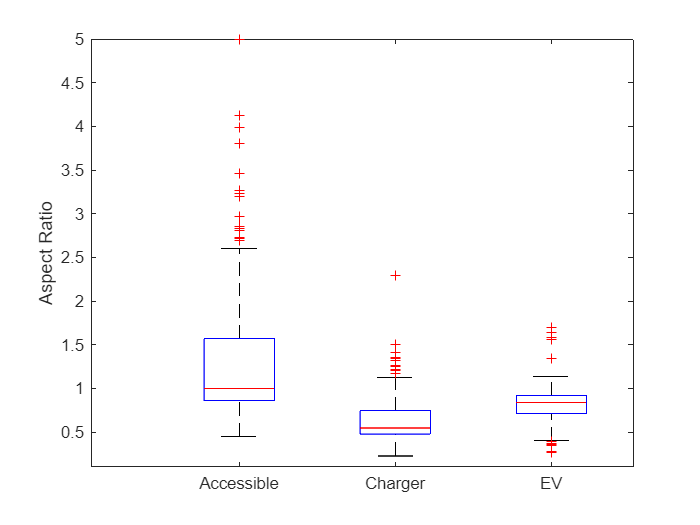

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

xlim([0.50 2.50])
ylim([1.60 5.08])

xlim([0.05 3.53])
ylim([0.1 4.26])

xlim([0.05 3.53])
ylim([0.10 5.00])

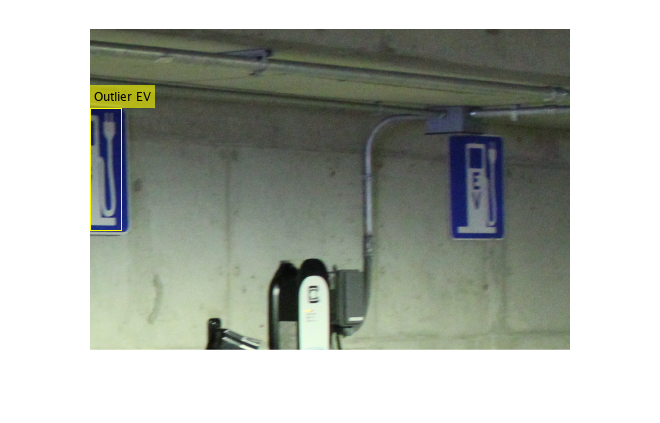

outlierIdx = 172;  % Index of the outlier bounding box
outlierImgNumber = bboxes.ImgIdx(outlierIdx);  % Image number corresponding to the outlier bounding box
outlierBBox = bboxes.BBox(outlierIdx, :);  % Bounding box coordinates of the outlier
outlierImg = readimage(imds, outlierImgNumber);  % Read the image from the image datastore
annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier EV");  % Annotate the image with a rectangle around the outlier
imshow(annotatedImg)  % Display the annotated image

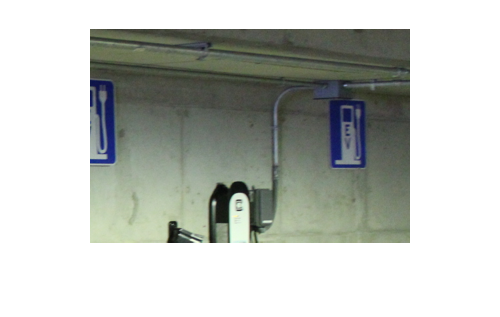

resizedImg = imresize(outlierImg, 2/3);
imshow(resizedImg)

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end